# **Week 7 : Optical Channel with 16QAM**

The code below implements an optical system with 16QAM with DSPs, and aims to investigate the feasibility of the model and the variation of the bit error rate (BER) with the signal-to-noise ratio (SNR)

## **Transmitter**

The model of the transmitter consists of the following elements:

- A symbol generator which modulates source bits using 16QAM

- A pulse shaper which creates an electrical signal using the generated symbols

- An IQ modulator which modulates the output of a laser according to an electrical signal

### Modulation

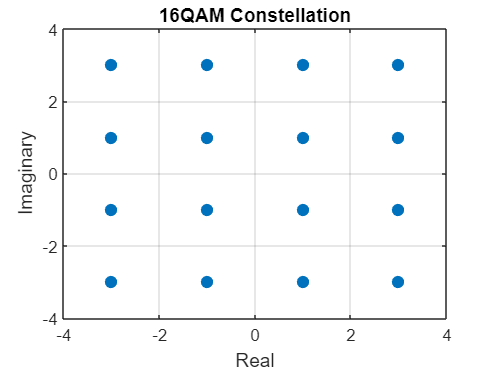

k = 4

symbols =   -3.0000 + 3.0000i  -3.0000 + 1.0000i  -3.0000 - 3.0000i  -3.0000 - 1.0000i  -1.0000 + 3.0000i  -1.0000 + 1.0000i  -1.0000 - 3.0000i  -1.0000 - 1.0000i   3.0000 + 3.0000i   3.0000 + 1.0000i   3.0000 - 3.0000i   3.0000 - 1.0000i   1.0000 + 3.0000i   1.0000 + 1.0000i   1.0000 - 3.0000i   1.0000 - 1.0000i


clear all; clearvars;

% Modulation parameters
M = 16; % Modulation order

% Visualising constellation
[k, symbols] = PlotConstellation("16QAM", 0)


% Generating random bit sequence(s)
NSymb = 500000; % No. of symbols 
SpS = 2; % Samples per symbol
Rs = 50e9; % Symbol rate in symbols/sec
NSequences = 11; % No. of bit sequences

sourceBits = randi([0 1], NSymb*k, NSequences) % Matrix of source bits

sourceBits =      0     1     1     0     1     0     1     1     0     1     0
     1     0     0     0     1     0     1     1     0     1     0
     0     0     0     1     1     0     0     1     0     1     0
     0     1     1     1     0     0     0     1     0     0     1
     1     0     0     1     1     0     1     0     1     1     0
     0     0     0     1     0     0     0     1     1     0     1
     1     0     1     0     1     0     1     0     1     0     1
     1     0     1     0     0     0     0     0     1     1     0
     0     1     1     1     1     0     0     0     1     1     1
     0     1     0     1     1     1     1     0     1     1     0


sourceInts = bit2int(sourceBits, k)

sourceInts =      4     9     9     3    14     0    12    15     0    14     1
    11     0     3    12    10     0    10     4    15     9     6
     2    14    10    13    12     4     4     2    12    14    10
     0     0     8    10    15     7     3     3     4    12     3
     4     9    14     4     3     6    11    15     5     8     4
     2     9    10     0     7     9     6    15     9     4    12
     2    14     8     1    12     1     7    11     4     0     8
     9     6     6    13     5    14     9     7     3     6    10
     3     4    12     6    11    12     4    11    11    11    12
    13     2     4    13     1    11     9     9    13    13     2


sourceSymbols = qammod(sourceInts, M) % Maps source bit vector to symbol vector

sourceSymbols =   -1.0000 + 3.0000i   3.0000 + 1.0000i   3.0000 + 1.0000i  -3.0000 - 1.0000i   1.0000 - 3.0000i  -3.0000 + 3.0000i   1.0000 + 3.0000i   1.0000 - 1.0000i  -3.0000 + 3.0000i   1.0000 - 3.0000i  -3.0000 + 1.0000i
   3.0000 - 1.0000i  -3.0000 + 3.0000i  -3.0000 - 1.0000i   1.0000 + 3.0000i   3.0000 - 3.0000i  -3.0000 + 3.0000i   3.0000 - 3.0000i  -1.0000 + 3.0000i   1.0000 - 1.0000i   3.0000 + 1.0000i  -1.0000 - 3.0000i
  -3.0000 - 3.0000i   1.0000 - 3.0000i   3.0000 - 3.0000i   1.0000 + 1.0000i   1.0000 + 3.0000i  -1.0000 + 3.0000i  -1.0000 + 3.0000i  -3.0000 - 3.0000i   1.0000 + 3.0000i   1.0000 - 3.0000i   3.0000 - 3.0000i
  -3.0000 + 3.0000i  -3.0000 + 3.0000i   3.0000 + 3.0000i   3.0000 - 3.0000i   1.0000 - 1.0000i  -1.0000 - 1.0000i  -3.0000 - 1.0000i  -3.0000 - 1.0000i  -1.0000 + 3.0000i   1.0000 + 3.0000i  -3.0000 - 1.0000i
  -1.0000 + 3.0000i   3.0000 + 1.0000i   1.0000 - 3.0000i  -1.0000 + 3.0000i  -3.0000 - 1.0000i  -1.0000 - 3.0000i   3.0000 - 1.0000i   1.0000 -

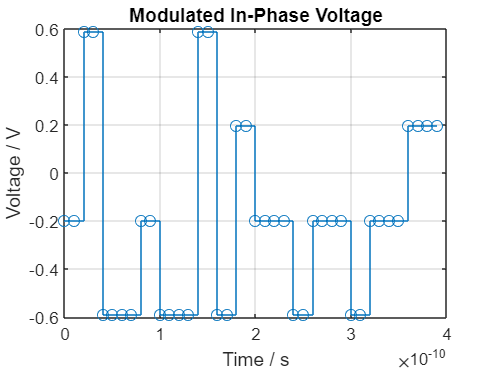


% 16QAM mapping

T = 1/(SpS*Rs); % Sampling period in s
t= [0:1:NSymb*SpS - 1]*T; % Time vector for plotting time-series data

% Modulating voltage with generated symbols
DCOffset = 0; % DC offset of modulated current in V
Vmax = 1; % Sets the maximum value of the voltage
voltageLevels = [-3*pi/16, -pi/16, pi/16, 3*pi/16]';

vI = ones(size(sourceSymbols));
vQ = ones(size(sourceSymbols));

% Mapping the distinct real & imaginary values to their respective voltage levels
vI(real(sourceSymbols)<=-2) = voltageLevels(1); 
vI(real(sourceSymbols)>-2 & real(sourceSymbols)<=0) = voltageLevels(2);
vI(real(sourceSymbols)>0 & real(sourceSymbols)<=2) = voltageLevels(3); 
vI(real(sourceSymbols)>2) = voltageLevels(4); 

vQ(imag(sourceSymbols)<=-2) = voltageLevels(1); 
vQ(imag(sourceSymbols)>-2 & imag(sourceSymbols)<=0) = voltageLevels(2);
vQ(imag(sourceSymbols)>0 & imag(sourceSymbols)<=2) = voltageLevels(3); 
vQ(imag(sourceSymbols)>2) = voltageLevels(4); 

vIupsampled = repelem(vI, SpS, 1); % Upsampling the voltage waveform based on SpS
vQupsampled = repelem(vQ, SpS, 1); % Upsampling the voltage waveform based on SpS

% Visualising in-phase and quadrature voltages
stairs(t(1:20*SpS), vIupsampled(1:20*SpS,1), "o-");
title("Modulated In-Phase Voltage")
xlabel("Time / s")
ylabel("Voltage / V")
grid on

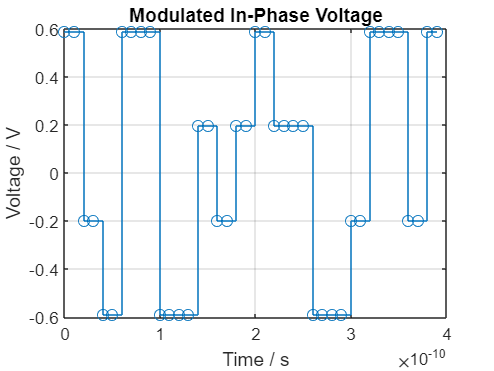


stairs(t(1:20*SpS), vQupsampled(1:20*SpS,1), "o-");
title("Modulated In-Phase Voltage")
xlabel("Time / s")
ylabel("Voltage / V")
grid on

### Adding AWGN

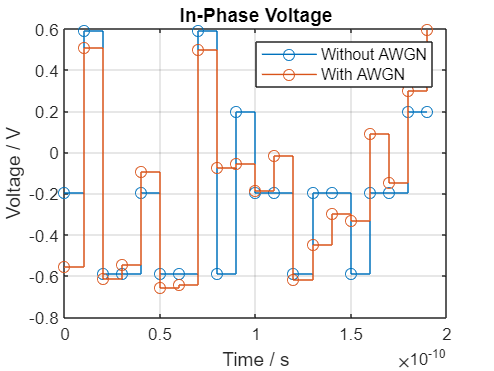

% Adding AWGN to the voltage waveforms before pulse shaping

SNRb_dB = [0:NSequences-1]'; % SNR per bit in dB
powerPerSymb = mean(voltageLevels.^2);
powerPerBit= powerPerSymb/k;

vUpsampled_AWGN = zeros(size(vIupsampled)); % Noisy signal to be continued without shaping
v_AWGN = zeros(size(vI)); % Noisy signal to be shaped 
for i=1:NSequences
    SNRb_Lin(i,1) = 10^(SNRb_dB(i,1)/10); % linear SNR per symbol
    AWGN_StdDev(i,1) = sqrt(powerPerSymb/SNRb_Lin(i,1)); % AWGN Standard deviation

    v_AWGN(:,i) = awgn(vI(:,i)+1i*vQ(:,i), convertSNR(SNRb_dB(i),'ebno', samplespersymbol=1, bitspersymbol=k), 'measured');
    vUpsampled_AWGN(:,i) = awgn(vIupsampled(:,i)+1i*vQupsampled(:,i), convertSNR(SNRb_dB(i),'ebno', samplespersymbol=1, bitspersymbol=k), 'measured');
end

% Debugging AWGN addition
% Visualising in-phase voltage with and without noise
stairs(t(1:10*SpS), vI(1:10*SpS,1), '-o');
hold on 
stairs(t(1:10*SpS), real(v_AWGN(1:10*SpS,1)), '-o');
title("In-Phase Voltage");
xlabel("Time / s");
ylabel("Voltage / V");
legend("Without AWGN", "With AWGN");
grid on
hold off

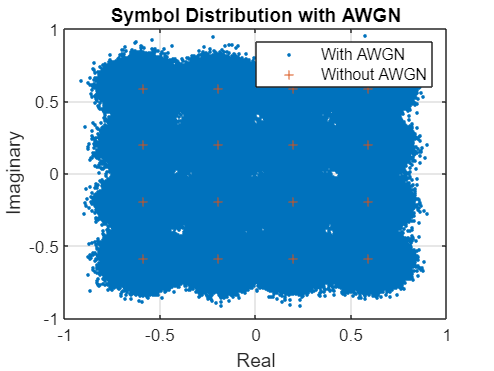


% Visualising symbol distribution with and without noise 
plot(v_AWGN(:,11), '.');
hold on
plot(vI(:,11), vQ(:,11), '+', MarkerSize=5);
title("Symbol Distribution with AWGN");
xlabel("Real");
ylabel("Imaginary");
legend("With AWGN", "Without AWGN");
grid on
hold off


% Premature decoding to check validity of AWGN model
% tempInts = pskdemod(vUpsampled_AWGN, M);
% tempBits = int2bit(tempInts, k);
% 
% for i=1:NSequences
%     [~, tempBER(i,1)] = biterr(sourceBits(:,i), downsample(tempBits(:,i), SpS));
% end
% 
% % Visualising BER vs SNR plot
% semilogy(SNRb_dB(1:11), 0.5*erfc(sqrt(10.^(SNRb_dB(1:11)/10))));
% hold on
% semilogy(SNRb_dB, tempBER, "-o");
% title("BER vs SNR");
% xlabel("SNR per bit / dB");
% ylabel("BER");
% legend("Theoretical", "Simulation")
% grid on
% hold off



### Pulse Shaping

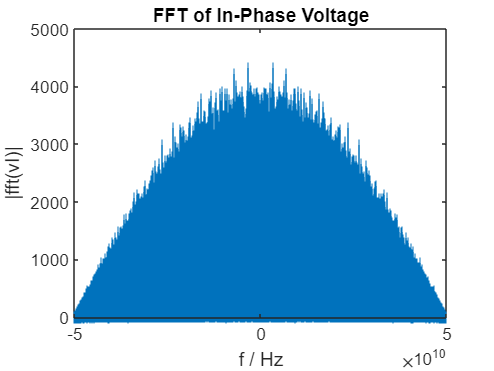

% Frequency spectrum of voltage waveform before filtering
fft_vI = fftshift(fft(vIupsampled(:,11))); % FFT without AWGN
freqArr = [-NSymb*SpS/2:NSymb*SpS/2 - 1]/(T*NSymb*SpS);
stem(freqArr, abs(fft_vI), "|");
title("FFT of In-Phase Voltage");
xlabel("f / Hz");
ylabel("|fft(vI)|");

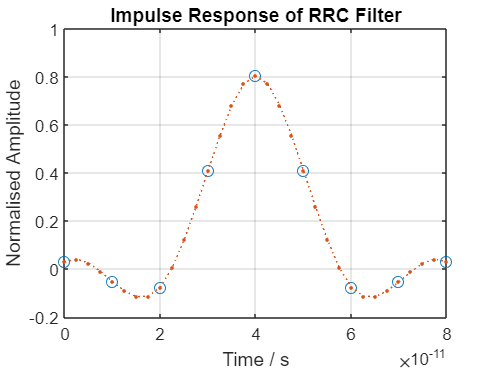


% RRC filter
filterSpan = 4; % Span of RRC filter in no. of symbols
rollOff = 0.5;
filterResponse = rcosdesign(rollOff, filterSpan, SpS)';

% Visualisation of RRC filter
filterResponse_t = [0:1:filterSpan*SpS]*T; % time vector for the filter response
filterResponse_t_interp = [0:0.25:filterSpan*SpS]*T;
filterResponse_interp = interp1(filterResponse_t, filterResponse, filterResponse_t_interp, "spline");
plot(filterResponse_t, filterResponse, "o", filterResponse_t_interp, filterResponse_interp, ":.");
title('Impulse Response of RRC Filter');
xlabel('Time / s');
ylabel('Normalised Amplitude');
grid on

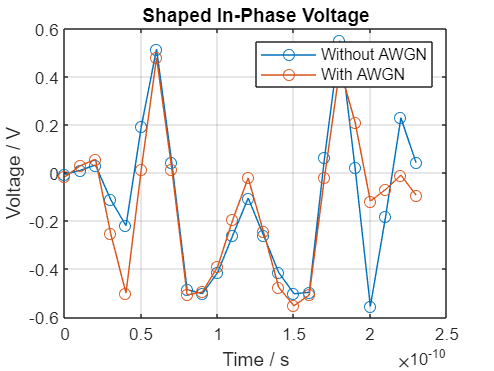


% Using RC filter to shape vI and vQ
% Without AWGN
vI_shaped = upfirdn(vI, filterResponse, SpS, 1); vQ_shaped = upfirdn(vQ, filterResponse, SpS, 1);
% With AWGN
vI_shaped_AWGN = upfirdn(real(v_AWGN), filterResponse, SpS, 1); vQ_shaped_AWGN = upfirdn(imag(v_AWGN), filterResponse, SpS, 1);


% Visualising pulse-shaped voltages
samples = 1+(NSymb-1)*SpS + filterSpan*SpS;
v_shaped_t = [0:1:samples-1]*T;
plot(v_shaped_t(1:10*SpS + filterSpan), vI_shaped(1:10*SpS + filterSpan,1), "o-");
hold on
plot(v_shaped_t(1:10*SpS + filterSpan), real(vI_shaped_AWGN(1:10*SpS + filterSpan,1)), "o-");
title("Shaped In-Phase Voltage");
ylabel("Voltage / V");
xlabel('Time / s');
legend("Without AWGN", "With AWGN");
grid on
hold off

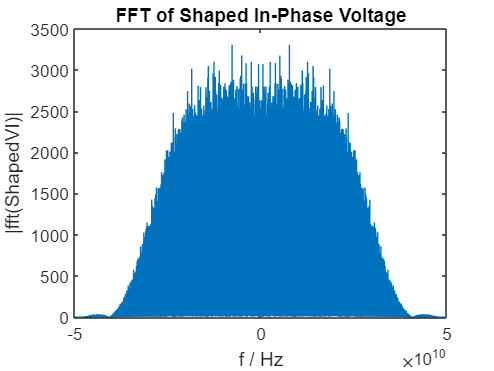

% Frequency spectrum of voltage waveform after filtering
fft_vI_shaped = fftshift(fft(vI_shaped(:,1)));
freqArr = [-samples/2:samples/2 - 1]/(T*samples);
plot(freqArr, abs(fft_vI_shaped));
title("FFT of Shaped In-Phase Voltage");
xlabel("f / Hz");
ylabel("|fft(ShapedVI)|");
hold off


bandwidth = 0.5*(1+rollOff)/T

bandwidth = 7.5000e+10


% Eye diagram of voltage waveform before filtering
% eyediagram(vI(1:1000,1), SpS);
% title("Eye Diagram of Discrete In-Phase Voltage")
% eyediagram(shapedVI(1:1000,1), SpS);
% title("Eye Diagram of Pulse-Shaped In-Phase Voltage")

### IQ Modulation

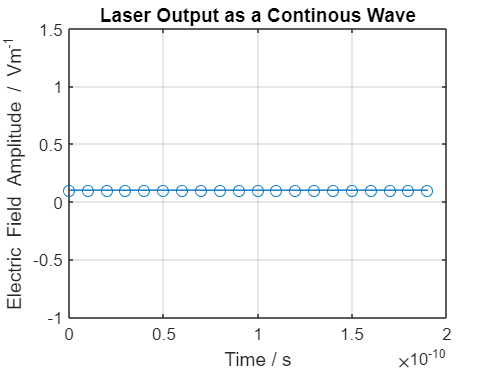

% Initialising laser parameters
lineWidth = 0;
laserPw_dBm = 10;
laserPw_Lin = 1e-3*10^(laserPw_dBm/10);

% Generating output from laser modelled as a contniuous-wave source
laserE = Laser(laserPw_dBm, lineWidth, SpS, Rs, NSymb, 1); % Laser output to be used with unshaped signals
laserE_shaped = Laser(laserPw_dBm, lineWidth, SpS, Rs, samples/SpS, 1); % Laser output to be used with shaped signals

% Visualising output from laser
t_interp = [0:0.25:NSymb*SpS - 1]*T;
plot(t(1:20), real(laserE(1:20)), "o-");
title("Laser Output as a Continous Wave");
xlabel("Time / s")
ylabel("Electric Field Amplitude / Vm^{-1}");
grid on

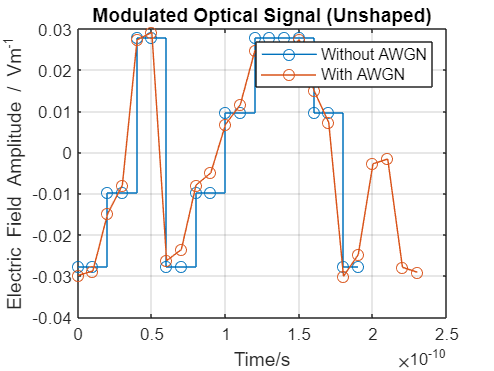


% Modulating optical signal using IQM
Vpi = pi/2; % Voltge required to change phase of E-field by pi
modOpticSig = IQModulatorModified(vIupsampled, vQupsampled, laserE, Vpi);
modOpticSig_AWGN = IQModulatorModified(real(vUpsampled_AWGN), imag(vUpsampled_AWGN), laserE, Vpi);
modOpticSig_shaped = IQModulatorModified(vI_shaped, vQ_shaped, laserE_shaped, Vpi);
modOpticSig_shaped_AWGN = IQModulatorModified(vI_shaped_AWGN, vQ_shaped_AWGN, laserE_shaped, Vpi);

% Visualising modulated optic signals
stairs(t(1:10*SpS), real(modOpticSig(1:10*SpS,11)), "o-");
hold on
plot(t(1:10*SpS+ filterSpan), real(modOpticSig_AWGN(1:10*SpS+ filterSpan, 11)), "o-");
title("Modulated Optical Signal (Unshaped)")
xlabel("Time/s")
ylabel("Electric Field Amplitude / Vm^{-1}")
legend("Without AWGN", "With AWGN")
grid on
hold off

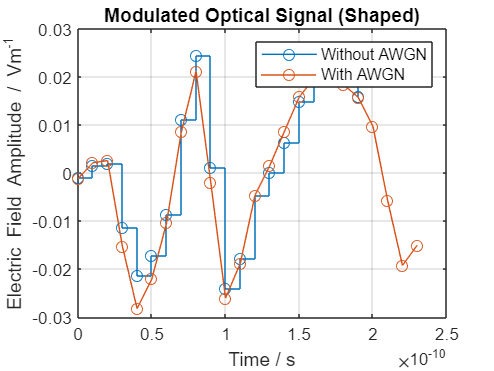


stairs(t(1:10*SpS), real(modOpticSig_shaped(1:10*SpS,11)), "o-");
hold on
plot(t(1:10*SpS+ filterSpan), real(modOpticSig_shaped_AWGN(1:10*SpS+ filterSpan, 11)), "o-");
title("Modulated Optical Signal (Shaped)")
xlabel("Time / s")
ylabel("Electric Field Amplitude / Vm^{-1}")
legend("Without AWGN", "With AWGN")
grid on
hold off

## Optical Channel

### Adding CD

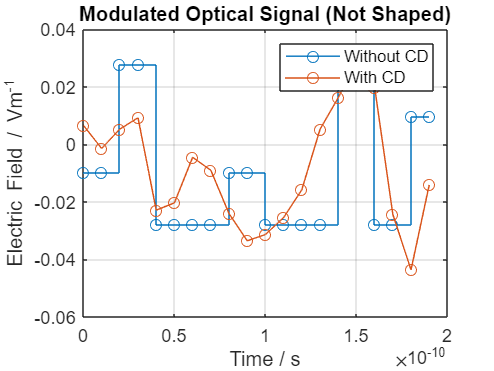

D = 17; % Group velocity dispersion in ps/nm/km
CLambda = 1550e-9; % Central wavelength of optical carrier in m
linkLength = 50e3; % Fibre link length in m

% eyediagram(real(modOpticSig(1:100,11)), SpS);

for i=1:NSequences
    modOpticSig_CD(:,i) = CDInsertion(modOpticSig(:,i), SpS, Rs, D, CLambda, linkLength, 1);
    modOpticSig_shaped_CD(:,i) = CDInsertion(modOpticSig_shaped(:,i), SpS, Rs, D, CLambda, linkLength, 1);
    modOpticSig_AWGN_CD(:,i) = CDInsertion(modOpticSig_AWGN(:,i), SpS, Rs, D, CLambda, linkLength, 1);
    modOpticSig_shaped_AWGN_CD(:,i) = CDInsertion(modOpticSig_shaped_AWGN(:,i), SpS, Rs, D, CLambda, linkLength, 1);
end

% Visualising optical signal before and after CD insertion:
% Without Pulse Shaping
stairs(t(1:10*SpS), real(modOpticSig(1:10*SpS,1)), "-o"); 
hold on
plot(t(1:10*SpS), real(modOpticSig_CD(1:10*SpS,1)), "-o");
xlabel("Time / s"); 
ylabel("Electric Field / Vm^{-1}")
title("Modulated Optical Signal (Not Shaped)")
legend("Without CD", "With CD")
grid on
hold off

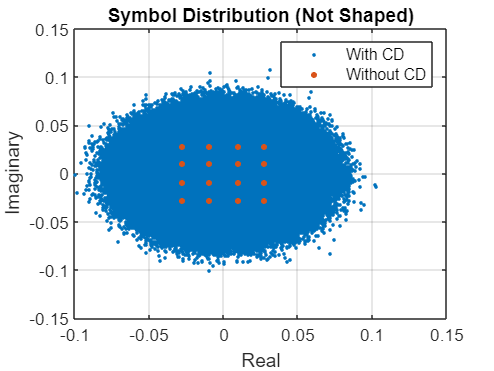


plot(real(modOpticSig_CD(:,1)), imag(modOpticSig_CD(:,1)), '.');
hold on
plot(real(modOpticSig(:,1)), imag(modOpticSig(:,1)), '.', "MarkerSize", 10);
xlabel("Real"); 
ylabel("Imaginary")
title("Symbol Distribution (Not Shaped)")
legend("With CD", "Without CD")
grid on
hold off

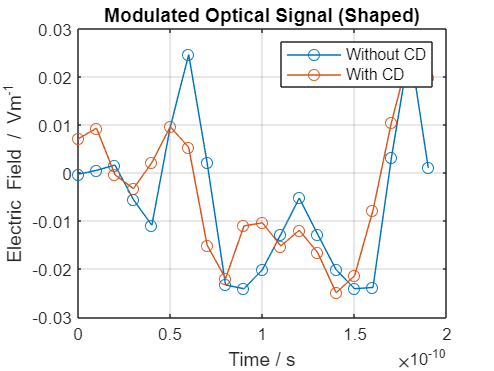

% -------------------------------------------------------------------------------

% With Pulse Shaping
plot(t(1:10*SpS), real(modOpticSig_shaped(1:10*SpS,1)), "-o"); 
hold on
plot(t(1:10*SpS), real(modOpticSig_shaped_CD(1:10*SpS,1)), "-o");
xlabel("Time / s"); 
ylabel("Electric Field / Vm^{-1}")
title("Modulated Optical Signal (Shaped)")
legend("Without CD", "With CD")
grid on
hold off

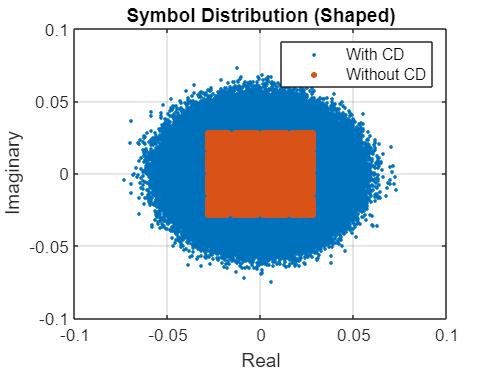


plot(real(modOpticSig_shaped_CD(:,1)), imag(modOpticSig_shaped_CD(:,1)), '.');
hold on
plot(real(modOpticSig_shaped(:,1)), imag(modOpticSig_shaped(:,1)), '.', "MarkerSize", 10);
xlabel("Real"); 
ylabel("Imaginary")
title("Symbol Distribution (Shaped)")
legend("With CD", "Without CD")
grid on
hold off


% % Premature CD compensation to check model feasibility
% c = 299792458; % Speed of light
% N_CD = ceil(6.67*(D*1e-6)*(CLambda^2)*linkLength*(Rs^2)*SpS/(2*pi*c)); % CD Equalizer Length
% Np = 2*ceil(sqrt((pi*c*T^2)^2 + (2*(D*10e-6)*linkLength*CLambda^2)^2)/(pi*c*T^2)) + 2;
% 
% for i=1:NSequences
%     modOpticSig_CDC(:,i) = OverlapSaveCDC(modOpticSig_CD(:,i), D, linkLength, CLambda, Rs, 1, SpS, 2e5, N_CD);
% end
% 
% % Visualising symbols after CD compensation
% plot(real(modOpticSig_CDC(:,1)), imag(modOpticSig_CDC(:,1)), '.');
% xlabel("Real"); 
% ylabel("Imaginary")
% title("Symbol Distribution after CD Compensation")
% grid on 


% eyediagram(real(modOpticSig(1:100,11)), SpS);

## Receiver

### Optical Front-End

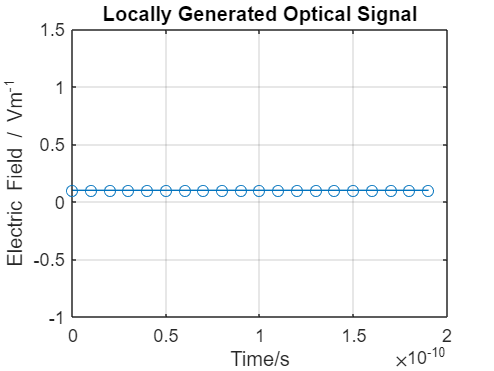

% Generating Local optical signal for coherent detection
Elo = laserE; % Identical to initial laser source
Elo_shaped = laserE_shaped;

% Visualising locally generated optical signal
plot(t(1:20), real(Elo(1:20,1)), "-o");
title("Locally Generated Optical Signal")
xlabel("Time/s")
ylabel("Electric Field / Vm^{-1}")
grid on

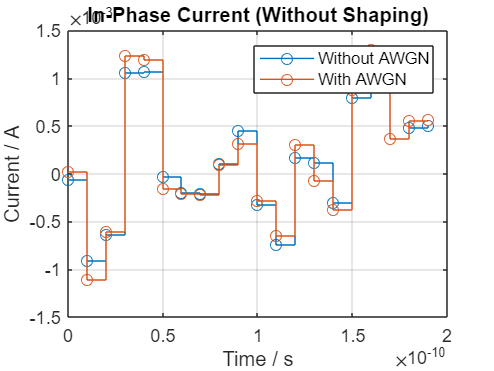


% Generating output from optical front-end
eta_ph = 0.3; % Responsivity of photodetectors

count = 1;

for i=1:size(modOpticSig,2)
    % Output from Optical Front-End
    OpticFEOut(:,count:count+1) = OpticalFrontEnd(modOpticSig_CD(:,i), Elo, eta_ph, 1);
    OpticFEOut_AWGN(:,count:count+1) = OpticalFrontEnd(modOpticSig_AWGN_CD(:,i), Elo, eta_ph, 1);
    OpticFEOut_shaped(:,count:count+1) = OpticalFrontEnd(modOpticSig_shaped_CD(:,i), Elo_shaped, eta_ph, 1);
    OpticFEOut_shaped_AWGN(:,count:count+1) = OpticalFrontEnd(modOpticSig_shaped_AWGN_CD(:,i), Elo_shaped, eta_ph, 1);
    count = count+2;
end

stairs(t(1:10*SpS), OpticFEOut(1:10*SpS,21), "-o"); % In-phase current
hold on
stairs(t(1:10*SpS), OpticFEOut_AWGN(1:10*SpS,21), "-o")
title("In-Phase Current (Without Shaping)")
xlabel("Time / s")
ylabel("Current / A")
legend("Without AWGN", "With AWGN")
grid on
hold off

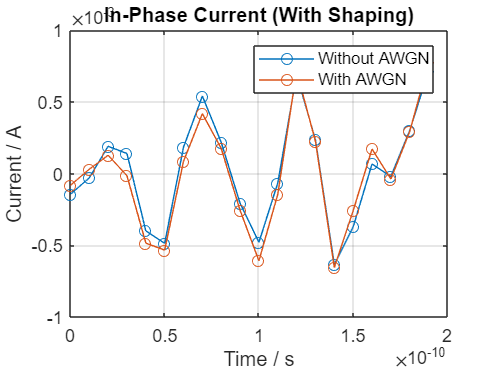


plot(t(1:10*SpS), OpticFEOut_shaped(1:10*SpS,21), "-o"); % In-phase current
hold on
plot(t(1:10*SpS), OpticFEOut_shaped_AWGN(1:10*SpS,21), "-o")
title("In-Phase Current (With Shaping)")
xlabel("Time / s")
ylabel("Current / A")
legend("Without AWGN", "With AWGN")
grid on
hold off


% TIA amplification and sampling using ADC
TIA_Gain = 1; % TIA amplification factor
Fs = SpS; % Sampling frequency of ADC

% Amplification and separation of in-phase and quadrature components
OpticalFEOut_I = TIA_Gain*OpticFEOut(1:end, 1:2:end); OpticalFEOut_I_AWGN = TIA_Gain*OpticFEOut_AWGN(1:end, 1:2:end);
OpticalFEOut_Q = TIA_Gain*OpticFEOut(1:end, 2:2:end); OpticalFEOut_Q_AWGN = TIA_Gain*OpticFEOut_AWGN(1:end, 2:2:end);
OpticalFEOut_I_shaped = TIA_Gain*OpticFEOut_shaped(:, 1:2:end); OpticalFEOut_I_shaped_AWGN = TIA_Gain*OpticFEOut_shaped_AWGN(:, 1:2:end);
OpticalFEOut_Q_shaped = TIA_Gain*OpticFEOut_shaped(:, 2:2:end); OpticalFEOut_Q_shaped_AWGN = TIA_Gain*OpticFEOut_shaped_AWGN(:, 2:2:end);


## DSP

### CD Compensation

% Scaling factor between output of IQM and output of optical front-end
laserEMag = sqrt(laserPw_Lin);
scaleFactor = TIA_Gain*eta_ph*laserEMag*laserEMag/2;

% Cancelling the scaling factor:
% NOT Shaped
voltageI_scaled = OpticalFEOut_I/scaleFactor; voltageQ_scaled = OpticalFEOut_Q/scaleFactor; 
voltageI_AWGN_scaled = OpticalFEOut_I_AWGN/scaleFactor; voltageQ_AWGN_scaled = OpticalFEOut_Q_AWGN/scaleFactor; 
% Shaped
voltageI_shaped_scaled = OpticalFEOut_I_shaped/scaleFactor; voltageQ_shaped_scaled = OpticalFEOut_Q_shaped/scaleFactor; 
voltageI_shaped_AWGN_scaled = OpticalFEOut_I_shaped_AWGN/scaleFactor; voltageQ_shaped_AWGN_scaled = OpticalFEOut_Q_shaped_AWGN/scaleFactor; 


% CD Compensation
c = 299792458; % Speed of light
N_CD = ceil(6.67*(D*1e-6)*(CLambda^2)*linkLength*(Rs^2)*SpS/(2*pi*c)); % CD Equalizer Length
N_FFT = 2^9;

for i=1:NSequences
    voltage_CDC(:,i) = OverlapSaveCDC(voltageI_scaled(:,i)+1i*voltageQ_scaled(:,i), D, linkLength, CLambda, Rs, 1, SpS, N_FFT, N_CD);
    voltage_shaped_CDC(:,i) = OverlapSaveCDC(voltageI_shaped_scaled(:,i)+1i*voltageQ_shaped_scaled(:,i), D, linkLength, CLambda, Rs, 1, SpS, N_FFT, N_CD);
    voltage_AWGN_CDC(:,i) = OverlapSaveCDC(voltageI_AWGN_scaled(:,i)+1i*voltageQ_AWGN_scaled(:,i), D, linkLength, CLambda, Rs, 1, SpS, N_FFT, N_CD);
    voltage_shaped_AWGN_CDC(:,i) = OverlapSaveCDC(voltageI_shaped_AWGN_scaled(:,i)+1i*voltageQ_shaped_AWGN_scaled(:,i), D, linkLength, CLambda, Rs, 1, SpS, N_FFT, N_CD);
end


% -------------------------------------------------------------------------
% Applying CD compensation using different FFT sizes
N_FFT_Arr = [7:15];
voltage_CDC_FFT = zeros(size(voltageI_shaped_scaled,1), length(N_FFT_Arr));

for i=1:length(N_FFT_Arr)
    voltage_CDC_FFT(:,i) = OverlapSaveCDC(voltageI_shaped_scaled(:,5)+1i*voltageQ_shaped_scaled(:,5), D, linkLength, CLambda, Rs, 1, SpS, 2^N_FFT_Arr(i), N_CD);
end

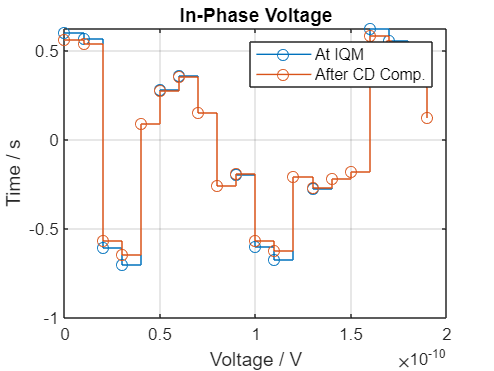


voltage_CDC_FFT = upfirdn(voltage_CDC_FFT, filterResponse, 1, SpS);
voltage_CDC_FFT = voltage_CDC_FFT(filterSpan + 1:end - filterSpan,:);

% -------------------------------------------------------------------------


% Visualisation of in-phase voltage at IQ modulator and after CD compensation
stairs(t(1:10*SpS), real(vUpsampled_AWGN(1:10*SpS,11)), '-o');
hold on
stairs(t(1:10*SpS), real(voltage_AWGN_CDC(1:10*SpS,11)), '-o');
title("In-Phase Voltage");
xlabel("Voltage / V");
ylabel("Time / s");
legend("At IQM", "After CD Comp.");
grid on
hold off

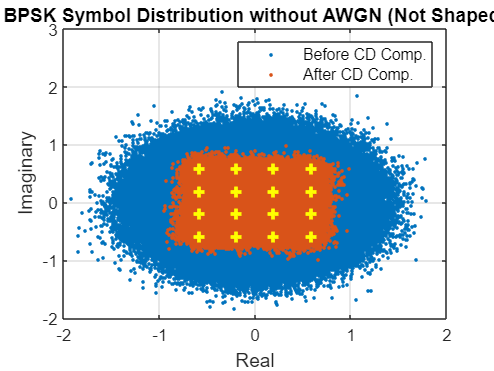



% Visualisation of symbols before and after CD compensation
plot(voltageI_scaled(:,1), voltageQ_scaled(:,1), '.')
hold on
plot(voltage_CDC(:,1), '.')
plot(sin(pi/16)*symbols, "y+", "LineWidth", 2)
title("BPSK Symbol Distribution without AWGN (Not Shaped)")
xlabel("Real")
ylabel("Imaginary")
legend("Before CD Comp.", "After CD Comp.")
grid on
hold off

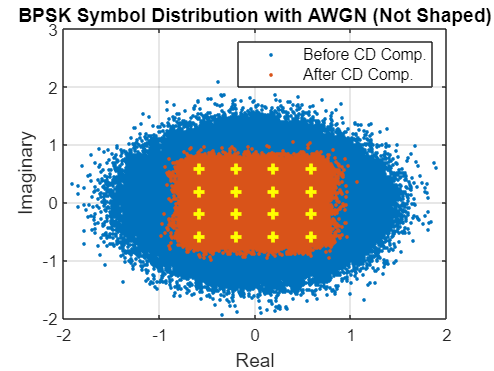


plot(voltageI_AWGN_scaled(:,11), voltageQ_AWGN_scaled(:,11), '.')
hold on
plot(voltage_AWGN_CDC(:,11), '.')
plot(sin(pi/16)*symbols, "y+", "LineWidth", 2)
title("BPSK Symbol Distribution with AWGN (Not Shaped)")
xlabel("Real")
ylabel("Imaginary")
legend("Before CD Comp.", "After CD Comp.")
grid on
hold off

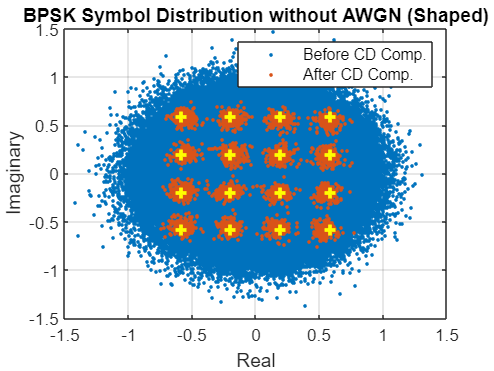


% Downsample unshaped signals after CD compensation
voltageI = real(voltage_CDC(1:SpS:end, :)); voltageQ = imag(voltage_CDC(1:SpS:end, :));
voltageI_AWGN = real(voltage_AWGN_CDC(1:SpS:end, :)); voltageQ_AWGN = imag(voltage_AWGN_CDC(1:SpS:end, :));

% Passing shaped components through matched filter and downsampling
voltageI_shaped = upfirdn(real(voltage_shaped_CDC), filterResponse, 1, SpS); voltageI_shaped = voltageI_shaped(filterSpan + 1:end - filterSpan,:);
voltageQ_shaped = upfirdn(imag(voltage_shaped_CDC), filterResponse, 1, SpS); voltageQ_shaped = voltageQ_shaped(filterSpan + 1:end - filterSpan,:);
voltageI_shaped_AWGN = upfirdn(real(voltage_shaped_AWGN_CDC), filterResponse, 1, SpS); voltageI_shaped_AWGN = voltageI_shaped_AWGN(filterSpan + 1:end - filterSpan,:);
voltageQ_shaped_AWGN = upfirdn(imag(voltage_shaped_AWGN_CDC), filterResponse, 1, SpS); voltageQ_shaped_AWGN = voltageQ_shaped_AWGN(filterSpan + 1:end - filterSpan,:);

plot(voltageI_shaped_scaled(:,1), voltageQ_shaped_scaled(:,1), '.')
hold on
plot(voltageI_shaped(:,1), voltageQ_shaped(:,1), '.')
plot(sin(pi/16)*symbols, "y+", "LineWidth", 2)
title("BPSK Symbol Distribution without AWGN (Shaped)")
xlabel("Real")
ylabel("Imaginary")
legend("Before CD Comp.", "After CD Comp.")
grid on
hold off

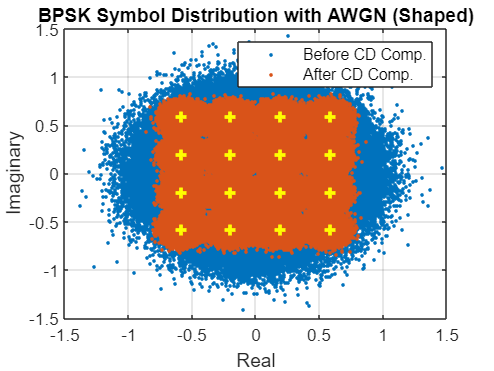


plot(voltageI_shaped_AWGN_scaled(:,11), voltageQ_shaped_AWGN_scaled(:,11), '.')
hold on
plot(voltageI_shaped_AWGN(:,11), voltageQ_shaped_AWGN(:,11), '.')
plot(sin(pi/16)*symbols, "y+", "LineWidth", 2)
title("BPSK Symbol Distribution with AWGN (Shaped)")
xlabel("Real")
ylabel("Imaginary")
legend("Before CD Comp.", "After CD Comp.")
grid on
hold off

### Decision

% Mapping scaled voltages to inital in-phase component of the symbol
% constellation.
% Maximum likelihood estimation, based on the Euclidian distance between the recieved voltage points
% and those corresponding to the symbols, is used.

% Taking the inverse of the IQ modulator transfer function
voltageI = asin(voltageI); voltageQ = asin(voltageQ);
voltageI_AWGN = asin(voltageI_AWGN); voltageQ_AWGN = asin(voltageQ_AWGN);
voltageI_shaped = asin(voltageI_shaped); voltageQ_shaped = asin(voltageQ_shaped);
voltageI_shaped_AWGN = asin(voltageI_shaped_AWGN); voltageQ_shaped_AWGN = asin(voltageQ_shaped_AWGN);

% Converting from downscaled voltage values to original symbols
voltageI = voltageI/(pi/16); voltageQ = voltageQ/(pi/16);
voltageI_AWGN = voltageI_AWGN/(pi/16); voltageQ_AWGN = voltageQ_AWGN/(pi/16);
voltageI_shaped = voltageI_shaped/(pi/16); voltageQ_shaped = voltageQ_shaped/(pi/16);
voltageI_shaped_AWGN = voltageI_shaped_AWGN/(pi/16); voltageQ_shaped_AWGN = voltageQ_shaped_AWGN/(pi/16);

% Decision and decoding
decodedSymbols = voltageI + 1i*voltageQ

decodedSymbols =   -1.0185 + 3.0008i   3.0074 + 0.9916i   3.0456 + 1.0397i  -2.9946 - 1.0039i   0.9997 - 2.9697i  -3.0721 + 3.0111i   0.9799 + 3.0093i   1.0093 - 0.9826i  -3.0171 + 3.0055i   0.9868 - 2.9873i  -2.9851 + 0.9943i
   2.9828 - 0.9992i  -2.9955 + 2.9922i  -2.9617 - 0.9685i   1.0047 + 2.9955i   2.9996 - 2.9754i  -3.0600 + 3.0108i   2.9810 - 2.9929i  -0.9918 + 3.0166i   0.9883 - 0.9959i   2.9873 + 1.0089i  -0.9906 - 3.0057i
  -3.0140 - 2.9992i   1.0023 - 3.0063i   3.0330 - 2.9695i   1.0046 + 0.9964i   0.9995 + 3.0206i  -1.0433 + 3.0101i  -1.0135 + 3.0054i  -2.9915 - 2.9863i   0.9902 + 3.0042i   0.9908 - 2.9912i   3.0085 - 3.0047i
  -3.0116 + 3.0007i  -2.9986 + 2.9949i   3.0286 + 3.0257i   3.0052 - 3.0040i   0.9994 - 0.9852i  -1.0376 - 0.9921i  -3.0137 - 0.9965i  -2.9924 - 0.9902i  -1.0083 + 3.0037i   0.9920 + 3.0076i  -2.9933 - 1.0033i
  -1.0083 + 3.0006i   3.0006 + 0.9964i   1.0213 - 2.9780i  -0.9957 + 2.9962i  -3.0008 - 0.9872i  -1.0331 - 2.9914i   2.9880 - 0.9973i   1.0058 

decodedInts = qamdemod(decodedSymbols, M);
decodedBits = int2bit(decodedInts, k);
biterr(decodedBits, sourceBits)

decodedSymbols_AWGN = voltageI_AWGN + 1i*voltageQ_AWGN;
decodedInts_AWGN = qamdemod(decodedSymbols_AWGN, M);
decodedBits_AWGN = int2bit(decodedInts_AWGN, k);

decodedSymbols_shaped = voltageI_shaped + 1i*voltageQ_shaped;
decodedInts_shaped= qamdemod(decodedSymbols_shaped, M);
decodedBits_shaped = int2bit(decodedInts_shaped, k);
biterr(decodedBits_shaped, sourceBits)

decodedSymbols_shaped_AWGN = voltageI_shaped_AWGN + 1i*voltageQ_shaped_AWGN;
decodedInts_shaped_AWGN= qamdemod(decodedSymbols_shaped_AWGN, M);
decodedBits_shaped_AWGN = int2bit(decodedInts_shaped_AWGN, k);

BER_BPSK_AWGN = zeros(NSequences,1); numErrors = zeros(NSequences,1);
BER_BPSK_AWGN_shaped = zeros(NSequences,1); numErrors_shaped = zeros(NSequences,1);

for i=1:NSequences
    [numErrors(i,1), BER_BPSK_AWGN(i,1)] = biterr(sourceBits(:,i), decodedBits_AWGN(:,i));
    [numErrors_shaped(i,1), BER_BPSK_AWGN_shaped(i,1)] = biterr(sourceBits(:,i), decodedBits_shaped_AWGN(:,i));
end

semilogy(SNRb_dB, (3/8)*erfc(sqrt(SNRb_Lin*2/5)));
hold on
semilogy(SNRb_dB, BER_BPSK_AWGN, '+');
semilogy(SNRb_dB, BER_BPSK_AWGN_shaped, 'o');
title("BER vs. SNR for 16-QAM");
ylabel("BER");
xlabel("SNR per bit / dB");
legend("Theoretical", "Unshaped", "Shaped");
grid on
hold off

% Investiagtion of variation of BER with filter size of CD compensator
decodedSymbolsFFT = (asin(real(voltage_CDC_FFT)) + 1i*asin(imag(voltage_CDC_FFT)))/(pi/16);
decodedIntsFFT = qamdemod(decodedSymbolsFFT, M);
decodedBitsFFT = int2bit(decodedIntsFFT, k);

for i=1:length(N_FFT_Arr)
    [~, BER_FFT(i,1)] = biterr(sourceBits(:,5), decodedBitsFFT(:,i));
end

semilogy(N_FFT_Arr, BER_FFT, '-o');
title("BER vs. FFT Size");
ylabel("BER");
xlabel("FFT Size");
grid on
hold off